# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

** Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

** Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Paula Fernández Sánchez, Luis Ramos Triguero, María Díez Martínez**

**Fecha: 17/11/2026**

# Tema 4. Ejercicio 2. Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de los contornos exteriores de los objetos de una imagen y reconstruirlos utilizando únicamente una parte de sus componentes de baja frecuencia, analizando cómo influye el número de componentes utilizadas en la aproximación obtenida.

Las funciones proporcionadas centran internamente la transformada, de forma que al reducir el número de componentes se conservan las componentes de baja frecuencia y se eliminan progresivamente las de mayor frecuencia.

Step 1) Read Image

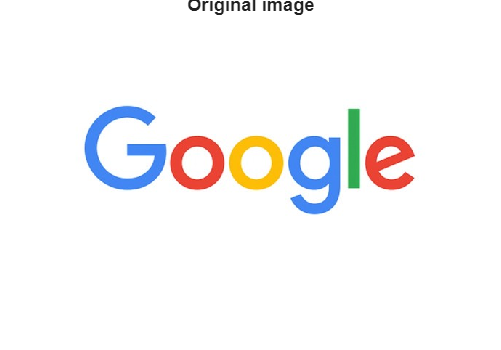

    
close all
    clear all

    imgOriginal = imread('google.jpg');
    figure;
    imshow(imgOriginal);
    title('Original image');

Step 2) Threshold the Image

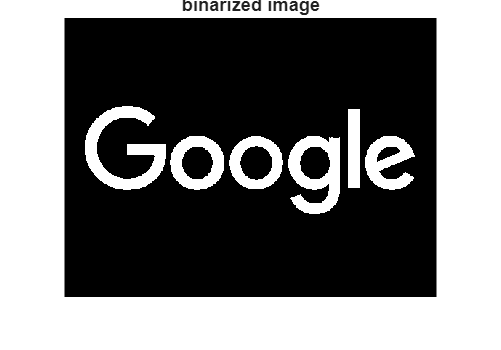

    if size(imgOriginal,3) == 3
        imgOriginal = rgb2gray(imgOriginal); 
    end
    imgBW = imbinarize(imgOriginal);
    imgBW = imcomplement(imgBW);
    
    figure;
    imshow(imgBW);
    title('binarized image');

Step 3) Find the external Boundaries

    [B,L] = bwboundaries(imgBW,'noholes');
    figure
    imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
    hold on
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
    end  

Step 4)  Fourier transform 

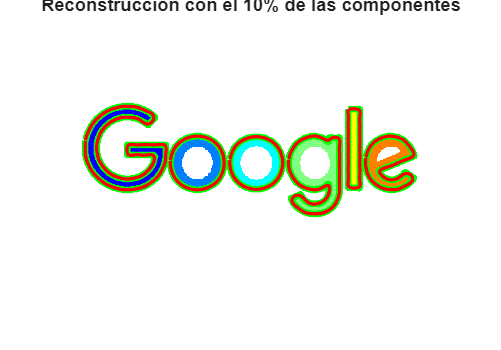

for k = 1:length(B)
   boundary = B{k};
   z = fourier_transform(boundary);      %  a partir de las boundaries
                                         % proporciona la transformada de Fourier
                                         % (listado de números complejos)
   nd = round(0.10*length(z));
   s = fourier_inv_transform(z, nd);     %  a partir de un número determinado de componentes de
                                          % la transformada de Fourier recupera las boundaries aproximadas
   title('Reconstrucción con el 10% de las componentes');
   plot(s(:,2), s(:,1), 'r', 'LineWidth', 2);   % plot recovered boundary
end

Se pide: 

- Complete el paso 4, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier del contorno de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Consulte los comentarios de la función para realizar la reconstrucción utilizando aproximadamente el **10 %** del total de componentes. Dibuje cada contorno reconstruido sobre la figura original utilizando `hold on` y compruebe visualmente cómo se ajusta al contorno original.

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 5**%** del total**.**

- Repita el proceso reduciendo el número de componentes utilizados para la reconstrucción al 2**%** del total

- Compare los resultados obtenidos con los tres porcentajes. Explique qué ocurre al reducir el número de componentes y relacione el resultado con la información representada por las componentes de baja y alta frecuencia. 

JUSTIFICACION: Con el 10 % el contorno reconstruido se ajusta casi perfecto al original. Con el 5 % se pierden las esquinas y los detalles finos, y con el 2 % las letras quedan como manchas redondeadas que solo conservan la forma general. Esto pasa porque las componentes de baja frecuencia guardan la forma global del objeto y las de alta frecuencia los detalles y las esquinas, que son las que vamos quitando.

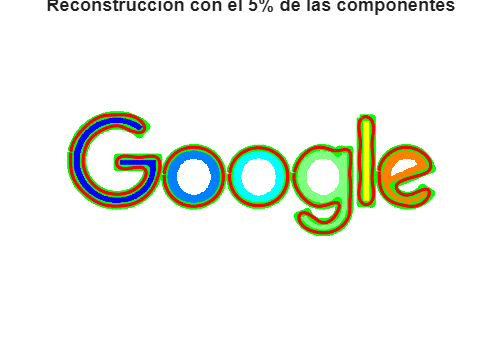

figure
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
   z = fourier_transform(boundary);
   nd = round(0.05*length(z));
   s = fourier_inv_transform(z, nd);
   title('Reconstrucción con el 5% de las componentes');
   plot(s(:,2), s(:,1), 'r', 'LineWidth', 2);
end

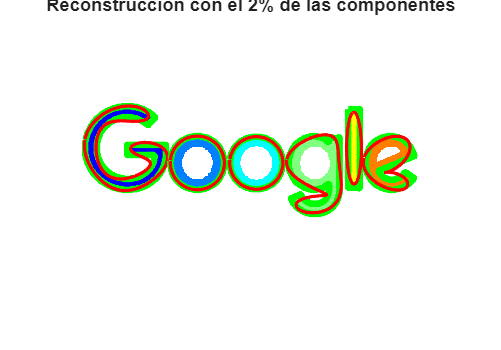


figure
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for k = 1:length(B)
   boundary = B{k};
   plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
   z = fourier_transform(boundary);
   nd = round(0.02*length(z));
   s = fourier_inv_transform(z, nd);
   title('Reconstrucción con el 2% de las componentes');
   plot(s(:,2), s(:,1), 'r', 'LineWidth', 2);
end